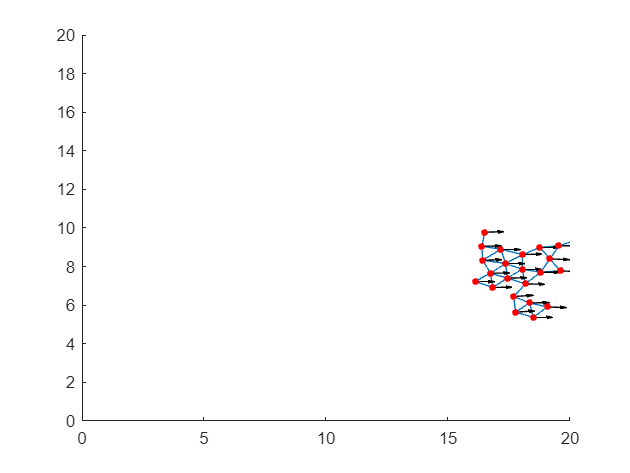

horizon = 1000; % time horizon of the simuation
% Set up the figure ahorizon = 500; % time horizon of the simuation
dt = 0.01; % delta time
t = 0;

% Set up the figure and axis
% figure('Position', [100 100 800 600]);
limit = 10;
% axis([0 limit 0 limit]);
% axis square;
hold on;

% Set up the region
% x = linspace(0, limit, 100);
% y = linspace(0, limit, 100);

% Initialize the boids
num_boids = 25;
% q = q;
% p = p;
[q, p] = generate_boids(num_boids, limit, limit/50);
p = ones(num_boids, 2);
% q = [0.3,0;1,0];
% p = [1.6,0;1.4,0];
max_vel = 2;
min_vel = 1;
max_accel = 5;
num_collisions = 0;
collisions = zeros(horizon, 1);

forces = zeros(horizon, 2);

max_distances = zeros(horizon, 1); % maximum distance between two neighbours
average_distances = zeros(horizon, 1); % average --
min_distances = zeros(horizon, 1); % minimum --

H_p = zeros(horizon, 1); % energy function - ||p|| squared
H_v = zeros(horizon, 1); % energy function - ||v|| squared

velocities = zeros(horizon, 2);

% System Params
epsilon = 1;
d = 0.07*limit;
kappa = 9.8/7;
r = kappa*d;
h = 0.2;
phi_max = 30;
g = 9.8;
% weights for the forces
gradient_coeff = 1;
consensus_coeff = 0.0;
turning_coeff = 1e6;

% A lower bound on inter-agent distance, beyond which we consider a collision
d_th = 0.1;

sys_params = [epsilon, d, kappa, h, max_accel, phi_max, g, gradient_coeff, consensus_coeff, turning_coeff, t];

% Update Loop
for i = 1:horizon
    t = t+dt;
    neighbours = findNeighbours(q, q, r);
    sys_params(11) = t;

    f = zeros(num_boids, 2);

    for j = 1:num_boids
        
        neighbours_of_j = neighbours{j};
        % Find the force acting on the jth boid
        j;
        force_on_j = generate_force(q, p, j, sys_params, false);
        f(j,:) = force_on_j;

    end

    % get the adjacency mmatrix (measures connectivity of the formation)
    a = get_unweighted_adjacency_matrix(q, r);
    g = get_weighted_adjacency_matrix(q, r);
    
    % disp(g)

    G = graph(g);
    l = laplacian(G);
    L = graph(l);
    
    comp_numbers = conncomp(L); % gives which connected component each agent belongs to
    % unique(comp_numbers)

    % form the groups
    % Get the unique IDs
    unique_ids = unique(comp_numbers);
    
    % Initialize the cell array
    cell_array = cell(1, numel(unique_ids));
    
    % Iterate through each unique ID
    for k = 1:numel(unique_ids)
        % Find indices where ID equals the unique ID
        indices = find(comp_numbers == unique_ids(k));
        % Store the indices in the cell array
        cell_array{k} = indices;
    end

    q_groups = zeros(size(cell_array, 2), 2);
    p_groups = zeros(size(cell_array, 2), 2);
    for j = 1:size(cell_array, 2)
        q_groups(j, :) = mean(q(cell_array{j}, :), 1);
        p_groups(j, :) = mean(p(cell_array{j}, :), 1);
    end

    f_k = zeros(size(cell_array, 2), 2);
    
    % size(cell_array)
    q_groups;
    for k = 1:size(cell_array, 2)
        force_on_k = generate_force(q_groups, p_groups, k, sys_params, true);
        f_k(k, :) = force_on_k;
    end
    % f_k + f;

    for j = 1:num_boids

        j;
        force_on_j = f(j,:) + f_k(comp_numbers(j), :);
        % force_on_j = f(j,:);

        % force_on_j = force_on_j - 1*(q(j,:) - [5,5]);
        % force_on_j = force_on_j;

        %-------------------------- actuator saturation -----------------
        % if vecnorm(force_on_j, 2, 2) > max_accel
        %     force_on_j = (max_accel/vecnorm(force_on_j, 2, 2)) * force_on_j;
        % end

        % ------------------------- velocity control --------------------
        % update velocity
        p(j,:) = force_on_j(1) * (p(j,:) / vecnorm(p(j,:),2,2)) * dt + p(j,:);
        dtheta = force_on_j(2) * dt;
        p(j,:) = ([cos(dtheta), sin(dtheta); -sin(dtheta), cos(dtheta)] * p(j,:)')';
        speed = vecnorm(p(j,:), 2, 2);
        if vecnorm(p(j,:), 2, 2) > max_vel
            p(j,:) = max_vel/speed * p(j,:); % cap the velocity at max_vel
        elseif vecnorm(p(j,:),2,2) < min_vel
            p(j,:) = min_vel/speed * p(j,:);
        end

        % forces(i, j) = force_on_j(1);
        % velocities(i, j) = speed;

        % p = real(p);
        % update position
        q(j,:) = q(j,:) + p(j,:)*dt;
        % q(j,:) = mod(q(j,:) + p(j,:)*dt, limit); % wraps the boids to within the frame -- exits left, enters right

    end

    % check for collisions
    collisions(i) = check_collisions(q, d_th);
    num_collisions = num_collisions + collisions(i);
    
    % Display the cell array
    % disp(cell_array);
    % cell_array{1}

    % get inter-agent distances
    max_distance = max(g, [], 'all'); % max distance between any two neighbours
    min_distance = min(g(g > 0), [], 'all'); % min distance between any two neighbours
    average_distance = mean(g(g > 0), "all"); % average distance all neighbours
    max_distances(i) = max_distance;
    if isempty(min_distance)
        min_distance = 0;
    else
        min_distances(i) = min_distance;
    end
    average_distances(i) = average_distance;

    % get velocities and positions of agents for plotting
    H_p(i) = 1/2 * sum(vecnorm(p, 2, 2));
    H_v(i) = 1/2 * sum(vecnorm(p - mean(p,1), 2, 2));

    s = sparse(g);
    xl = xlim;
    yl = ylim;
    dx = xl(2) - xl(1);
    dy = yl(2) - yl(1);
    delta = max(dx, dy);
    x_minimum = min(q(:,1));
    y_minimum = min(q(:,2));
    x_maximum = max(q(:,1));
    y_maximum = max(q(:,2));
    xlim([0, 20]);
    ylim([0, 20]);
    scalex = dx/25;
    scaley = dy/25;

    % xlim([0, limit]);
    % ylim([0, limit]);
    % plots the velocity vectors and positions
    cla;
    gplot(s,q); 
    quiver([q(:,1)], [q(:,2)], scalex*(p(:,1)./vecnorm(p,2,2)), scaley*(p(:,2)./vecnorm(p,2,2)), 0, 'Color', 'k'); 
    plot(q(:,1), q(:,2), 'ro', 'MarkerSize', 3.5, 'MarkerFaceColor','red');

    % save the plots at given time intervals
    % if mod(i, 295) == 5
    %     cla;
    %     gplot(s,q); 
    %     quiver([q(:,1)], [q(:,2)], scalex*(p(:,1)./vecnorm(p,2,2)), scaley*(p(:,2)./vecnorm(p,2,2)), 0, 'Color', 'k'); 
    %     plot(q(:,1), q(:,2), 'ro', 'MarkerSize', 3.5, 'MarkerFaceColor','red');
    %     title("t = " + num2str(i/100));
    %     plot_name = "turning_"+num2str(i/100)+".png";
    %     exportgraphics(gca, plot_name);
    % end 

    % prints the ids of the boids
    % for k = 1:num_boids
    %     text(p(k,1), p(k,2), string(k));
    % end

    % prints the deviation energy, defined in olfati-saber for alpha lattices
    % if mod(i, 1000) == 0
    %     devE = (0.5*sum(psi(g-d))) / (1 + 0.5*sum(a));
    % end

    pause(0.01);
    % if mod(i, 100) == 1
    %     dir = sum(p ./ vecnorm(p,2,2));
    %     dir/vecnorm(dir,2,2)
    % end
end

% hold off;

% plot(collisions);
% title("Collisions");
% plot_name = "Collisions.png";
% exportgraphics(gca, plot_name);
% 
% a1 = plot(max_distances, 'b-');
% hold on;
% plot(min_distances, 'b-');
% % Fill the area between the lines
% x_values = 1:numel(max_distances);
% fill([x_values fliplr(x_values)], [max_distances' fliplr(min_distances')], 'c', 'EdgeColor', 'none', 'FaceAlpha', 0.2);
% a2 = plot(average_distances, 'k-');
% a3 = plot([0, horizon], [d, d], 'g--');
% a4 = plot([0, horizon], [d_th, d_th], 'r--');
% hold off;
% legend([a1, a2, a3, a4], {'Maximum/Minimum', 'Average',  'Desired', 'Collision Boundary'})
% title("Inter-Agent Distances (Only Neighbours)");
% plot_name = "Interagent_distances.png";
% exportgraphics(gca, plot_name);
% 
% plot(H_v);
% title("CM Frame Velocity-Based Energy ($H = \frac{1}{2}\sum_i||p_i-\bar{p}||^2$)", Interpreter="latex");
% plot_name = "H_v.png";
% exportgraphics(gca, plot_name);
% 
% plot(H_p);
% title("Velocity-Based Energy ($H = \frac{1}{2}\sum_i||p_i||^2$)", Interpreter="latex");
% plot_name = "H_p.png";
% exportgraphics(gca, plot_name);

% plot(velocities);
% title("Velocities");
% plot(forces);
% title("Forces");

% p1 = p(p(:,2) > 0,:)
% p2 = p(p(:,2) < 0,:)
% delp = p2(1,:) - p1(1,:)
% delp(1)
% l = atan2(delp(1,2)*p1(1,1)-delp(1,1)*p1(1,2), delp(1,1)*p1(1,1)+delp(1,2)*p1(1,2))
% tanh(sin(l/2))
% vecnorm(l,2,2)*tanh(sin(l/2))

function out = generate_force(q, p, id, sys_params, flag)

    %-----------------------------------------------------------------
    function out = sigmaEpsilon(z, epsilon)
        out = z ./ sqrt(1 + epsilon*(vecnorm(z, 2, 2)));
    end

    function rho = bumpFunction(z, h)
        rho = zeros(size(z));
        rho(z >= 0 & z < h) = 1;
        rho(z >= h & z <= 1) = (1/2) * (1 + cos(pi * ((z(z >= h & z <= 1) - h)/(1 - h))));
    end

    function out = phi(z, a, b) 
        % merely scaling and shifting the sigmaEpsilon function
        c = abs(a-b)/sqrt(4*a*b);
        out = 0.5 * ((a+b) * sigmaEpsilon(z+c, 1) + (a-b));
    end

    function out  = phi_alpha(z, r_alpha, d_alpha, a, b)
        out = bumpFunction(z/r_alpha, 0.2) .* phi(z-d_alpha, a, b);
    end

    function out = sigmaNorm(z, epsilon)
        out = (1/epsilon) * (sqrt(1 + epsilon * vecnorm(z, 2, 2).^2) - 1);
    end

    function out = angle(v1, v2)
        v1;
        v2;
        cross = v1(2)*v2(1) - v1(1)*v2(2);
        dot = sum(v1 .* v2);
        out = atan2(cross, dot);
        if cross == 0 && dot < 0
            out = pi;
        end
    end
    %------------------------------------------------------------------

    % q(id,:) -- position of the jth boid
    % q(neighbour_ids,:) -- positions of the neighbouring boids
    % p(id,:) -- velocity of the jth boid
    % p(neighbour_ids,:) -- velocities of the neighbouring boids
    
    % ---------------------- system params ---------------------------
    epsilon = sys_params(1);
    d = sys_params(2);
    kappa = sys_params(3);
    if ~flag
        r = kappa * d;
        neighbours = findNeighbours(q(id, :), q, r);
        neighbours;
        q;
        neighbour_ids = neighbours{1};
    else
        distances = pdist2(q, q(id,:));
        distances(distances == 0) = inf;
        neighbour_ids = find(distances == min(distances));
        distances;
        neighbour_ids;
        min_x = min(distances);
        r = 2 * kappa * min_x / (kappa + 1);
        d = 2 * min_x / (kappa + 1);
        if r < kappa * sys_params(2)
            id;
            d = sys_params(2);
            r = kappa * d;
        end
        % pause(0.01)
    end
    h = sys_params(4);
    max_accel = sys_params(5);
    phi_max = sys_params(6);
    g = sys_params(7);
    C = g * tand(phi_max);
    
    gradient = sys_params(8);
    consensus = sys_params(9);
    turning = sys_params(10);
    t = sys_params(11);
    
    % --------------------- transformed params -----------------------
    r_alpha = sigmaNorm(r, epsilon);
    d_alpha = sigmaNorm(d, epsilon);
    
    heading = atan2(p(id, 2), p(id, 1));
    
    % --------------------- gradient term ----------------------------
    
    n_ij = sigmaEpsilon(q(neighbour_ids,:) - q(id,:), epsilon);
    u_grad = sum(phi_alpha(sigmaNorm(q(neighbour_ids,:) - q(id,:), epsilon), r_alpha, d_alpha, 50, 100) .* n_ij, 1);
    % u_grad = -sum(phi_alpha(sigmaNorm(q(neighbour_ids,:) - q(id,:), epsilon), r, d, 100000, 100000) .* n_ij, 1);
    
    % % --------------------- consensus term ---------------------------
    % a_ij = bumpFunction(sigmaNorm((q(neighbour_ids,:) - q(id,:)/r_alpha), epsilon), h);
    % % a_ij = bumpFunction(sigmaNorm((q(neighbour_ids,:) - q(id,:)/r), epsilon), h);
    % u_cons = sum(a_ij .* p(neighbour_ids,:) - p(id,:), 1);
    % 
    % %---------------------- linear acceleration term -----------------
    % lin_accel = 0;
    % sum_term1 = 0;
    % for j = 1:length(neighbour_ids)
    %     sum_term1 = sum_term1 + sum((p(j,:) - p(id,:)) .* [cos(heading), sin(heading)]);
    % end
    % lin_accel = tanh(sum_term1) * [cos(heading), sin(heading)];
    % 
    % %---------------------- turning term -----------------------------
    % u_turn = 0;
    % sum_term = 0;
    % for j = 1:length(neighbour_ids)
    %     delta_p = p(id,:) - p(j,:);
    %     eta_ij = atan2(delta_p(2) * p(id,1) - delta_p(1) * p(id,2), sum(delta_p .* p(id,:)));
    %     if eta_ij == 0 && sum(delta_p .* p(id,:)) < 0
    %         eta_ij = pi;
    %     end
    %     if isnan(eta_ij)
    %         eta_ij = 0;
    %     end
    %     sum_term = sum_term + sin(eta_ij / 2);
    % end
    % B = 1;
    % u_turn = -1 / vecnorm(p(id,:),2,2) * tanh(B*sum_term) * [-sin(heading), cos(heading)];
    % % --------------------- navigation term --------------------------
    % u_nav = [0, 0];
    % u_nav = -100*(q(id,:) - [5,5]);
    
    %-----------------------------------------------------------------
    
    % % u_grad
    % % u_cons
    % % u_turn
    % id;
    % % a_xy = gradient*u_grad + consensus*u_cons + u_nav;
    % u_grad = gradient*u_grad;
    % lin_accel_grad = sum(u_grad .* [cos(heading), sin(heading)]) * [cos(heading), sin(heading)];
    % turn_grad = sum(u_grad .* [-sin(heading), cos(heading)]) * [-sin(heading), cos(heading)];
    % 
    % total_lin_accel = lin_accel + lin_accel_grad;
    % total_turn = u_turn + turn_grad;
    % 
    % if abs(total_lin_accel) > max_accel
    %     total_lin_accel = sign(sum(total_lin_accel.*[cos(heading), sin(heading)])) * max_accel/vecnorm(total_lin_accel,2,2) * [cos(heading), sin(heading)];
    % end
    % 
    % if abs(total_turn) > C/vecnorm(p(id,:),2,2)
    %     total_turn = (C/vecnorm(p(id,:),2,2)) * (total_turn/vecnorm(total_turn,2,2));
    % end
    % 
    % a_xy = total_lin_accel + total_turn;
    % perp
    
    %-------- convert to x,y to linear,omega acceleration ------------
    % below is the desired control input
    
    % cap the control inputs and introduce delays 
    % if abs(out(1)) > max_accel
    %     out(1) = out(1)/abs(out(1)) * max_accel;
    % end
    % 
    % if abs(out(2)) > g*tan(phi_max*pi/180) / vecnorm(p(id,:), 2, 2)
    %     out(2) = g*tan(phi_max*pi/180) / vecnorm(p(id,:), 2, 2);
    % end
        
    %-----------------------------------------------------------------
    
    % u_grad + turning
    adj = bumpFunction(sigmaNorm((q - q(id,:)/r_alpha), epsilon), h);
    target_heading_vector = sum(p, 1);
    target_heading_vector = target_heading_vector / vecnorm(target_heading_vector,2,2);
    % target_heading_vector = target_heading_vector + 10*([-t, -t] - q(id, :));
    speed = vecnorm(p(id,:),2,2);
    direction = p(id,:) / speed;
    alpha = 5*angle(p(id,:), target_heading_vector);
    
    u_grad_parallel = sum(u_grad .* direction) * direction;
    acceleration = vecnorm(u_grad_parallel,2,2)*sign(sum(u_grad .* direction));
    
    u_grad_perp = u_grad - u_grad_parallel;
    turning = vecnorm(u_grad_perp, 2, 2);
    s = sign(sum(u_grad_perp .* [-direction(2), direction(1)]));
    turning = -s*turning;
    
    omega = (alpha/pi + turning) / speed;

    % Attempt a damping term
    damping_acceleration = 0;
    for j = 1:length(neighbour_ids)
        j;
        neighbour_ids;
        p;
        q_j = q(neighbour_ids(j), :);
        p_j = p(neighbour_ids(j), :);
        speed_j = vecnorm(p_j, 2, 2);
        gamma = angle(p(id, :), p_j);
        damping_acceleration = (speed_j*cos(gamma) - speed) * cos(gamma);
    end

    acceleration = acceleration + damping_acceleration;
    % omega = turning/speed;
    
    % if angle(p(id,:), [-1,0]) == 0
    %     u_grad
    %     u_grad_parallel
    %     u_grad_perp
    %     turning
    %     alpha
    %     omega
    % end
    
    out = [acceleration, omega];
    if flag
        out = out * 0.3;
    end

    if length(q) < 5
        id;
        q(id,:);
        p(id,:);
        out;
        pause(0.01);
    end

    % set NaN values to zero, else the boid disappears
    out(isnan(out)) = 0;

end


function out = psi(z)
 
    out = z.^2;

end


function neighbors = findNeighbours(boids, all_boids, range)
    
    neighbors = rangesearch(all_boids, boids, range);
    neighbors = cellfun(@(a) a(2:end), neighbors, 'UniformOutput', false);

end


function number_of_collisions = check_collisions(boids, threshold_distance)

    number_of_collisions = 0;
    distances = pdist2(boids, boids);
    crashes = zeros(size(boids,1));
    crashes(distances <= threshold_distance) = 1;
    crashes = crashes - eye(size(boids,1));
    number_of_collisions = sum(crashes, 'all');
    number_of_collisions = number_of_collisions / 2;

end


function out = get_unweighted_adjacency_matrix(points, range)

    function out = cell2logic(c, n)
    out = zeros(1, n);
    out(c) = 1;
    end

    neighbours = findNeighbours(points, points, range);
    out = cell2mat(cellfun(@(a) cell2logic(a, size(points, 1)),  neighbours, 'UniformOutput', false));

end


function out = get_weighted_adjacency_matrix(points, range)

    distances = pdist2(points, points);
    out = get_unweighted_adjacency_matrix(points, range) .* distances;

end